
% Only run once
clear
load('mnist_test.mat')
load('mnist_train.mat')

images_train = mnisttrain{: , (2:end)};
labels_train = mnisttrain{: , 1}

labels_train =      5
     0
     4
     1
     9
     2
     1
     3
     1
     4



images_test = mnisttest{: , (2:end)};

images_test =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     

labels_test = mnisttest{: , 1};

labels_test =      7
     2
     1
     0
     4
     1
     4
     9
     5
     9


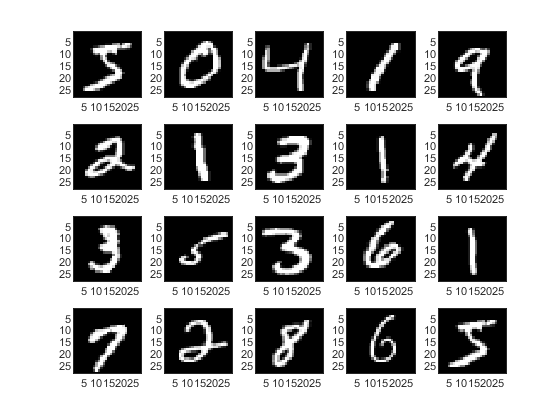


colormap gray
imagesc(reshape(images_train(1,:), 28,28)')

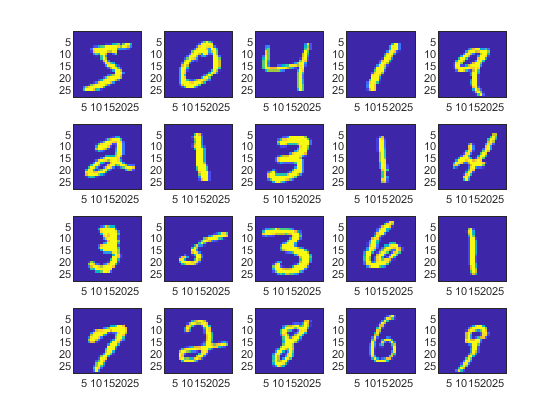


figure;
perm = randperm(60000,20);
for i = 1:20
 subplot(4,5,i);
 imagesc(reshape(images_train(i,:),28,28)')
end



model = fitcknn(images_train, labels_train, "NumNeighbors", 5, "Standardize", 1)

model =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1 2 3 4 5 6 7 8 9]
           ScoreTransform: 'none'
          NumObservations: 60000
                 Distance: 'euclidean'
             NumNeighbors: 5


  Properties, Methods


## Prediction phase (takes long time)



prediction = predict(model, images_test);

prediction =      7
     2
     1
     0
     4
     1
     4
     9
     4
     9


## measuring accuracy

correct = prediction == labels_test;
wrong = prediction ~= labels_test;

accuracy = sum(correct) / numel(prediction)

accuracy = 0.9445

missclassrate = sum(wrong) / numel(prediction)

missclassrate = 0.0555


confusionchart(images_test, prediction)

Undefined function or variable 'confusionchart'.